# Savitzky-Golay Filtering

A program which is developed based on Savitzky-Golay approach for smoothing rate-normalized pressure (RNP) data.

Author: Munthe, Felix A.

Created on Monday, 30 October 2023

## Import Data

### True RNP Data

clear; clc; clf;
opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["t", "RNP"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
true_RNP = readtable("C:\Users\ASUS\Documents\Kuliah\2. Master's Texas A&M University\Publications\Conference Paper\Smoothing Paper\Smoothing Simulator\true_RNP.txt", opts)

true_RNP = 1150×2 table
       t          RNP    
    _______    __________

       0.25    1.3616e+06
    0.33041    1.9565e+06
     0.4862    2.6089e+06
    0.79777    3.4782e+06
     1.4209    4.6953e+06
     2.6672    6.4232e+06
     5.0773    8.8236e+06
     9.8974    1.2258e+07
     19.198    1.7054e+07
     35.645    2.3347e+07
      66.06    3.1893e+07
     124.99    4.3906e+07
     188.99    5.4925e+07
     252.99    6.4572e+07
     316.99    7.3193e+07
     380.99     8.103e+07


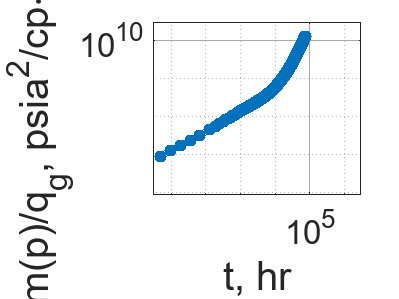


% Plot
loglog(true_RNP.t, true_RNP.RNP, ".", "MarkerSize", 25,"Color", "#0072BD");
% title("True RNP Data", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold off;

### Noisy RNP Data Set 186

opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["t", "RNP"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
noisy_RNP_186 = readtable("C:\Users\ASUS\Documents\Kuliah\2. Master's Texas A&M University\Publications\Conference Paper\Smoothing Paper\Smoothing Simulator\Noisy RNP Model\All\25%\noisy_data_6.txt", opts)

noisy_RNP_186 = 1150×2 table
       t          RNP    
    _______    __________

       0.25    1.3616e+06
    0.33041    1.9565e+06
     0.4862    2.6089e+06
    0.79777    2.2088e+08
     1.4209    4.6953e+06
     2.6672    6.4232e+06
     5.0773    8.8236e+06
     9.8974    1.2258e+07
     19.198    1.0575e+08
     35.645    2.3347e+07
      66.06    3.1893e+07
     124.99    4.3906e+07
     188.99    5.4925e+07
     252.99    6.4572e+07
     316.99    7.3193e+07
     380.99    2.4558e+07


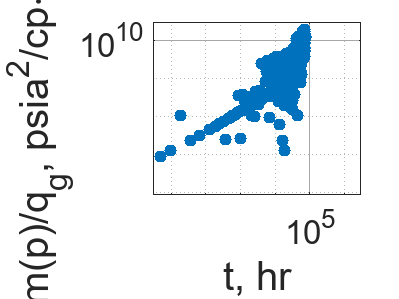


% Plot
loglog(noisy_RNP_186.t, noisy_RNP_186.RNP, ".", "MarkerSize", 25,"Color", "#0072BD");
% title("Noisy RNP Data Set 186", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold off;

## Smoothing

### Noisy RNP Data 186

logRNP_186 = log(noisy_RNP_186.RNP);

#### Window: 3

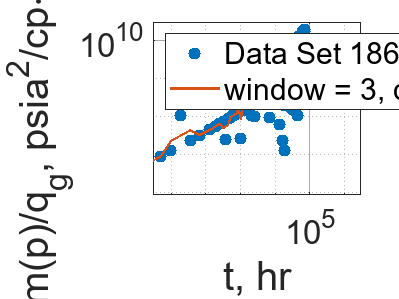

% Plot
loglog(noisy_RNP_186.t, noisy_RNP_186.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 186");
% title("Noisy RNP Data Set 186", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_186_31 = smooth(logRNP_186, 3, "sgolay", 1);
smoothedRNP_186_31 = exp(smoothedLogRNP_186_31);
residual_186_31 = (true_RNP.RNP - smoothedRNP_186_31) ./ (0.3413 .* true_RNP.RNP);
sse_186_31 = sum(residual_186_31 .^ 2);
loglog(noisy_RNP_186.t, smoothedRNP_186_31, "-", "LineWidth", 1.3, "DisplayName", "window = 3, degree = 1");
legend("Location", "northwest");
hold off;

### Window: 5

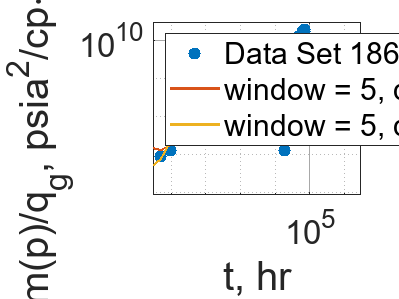

% Plot
loglog(noisy_RNP_186.t, noisy_RNP_186.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 186");
% title("Noisy RNP Data Set 186", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_186_51 = smooth(logRNP_186, 5, "sgolay", 1);
smoothedRNP_186_51 = exp(smoothedLogRNP_186_51);
residual_186_51 = (true_RNP.RNP - smoothedRNP_186_51) ./ (0.3413 .* true_RNP.RNP);
sse_186_51 = sum(residual_186_51 .^ 2);
loglog(noisy_RNP_186.t, smoothedRNP_186_51, "-", "LineWidth", 1.3, "DisplayName", "window = 5, degree = 1");
hold on;

% Degree = 2
smoothedLogRNP_186_52 = smooth(logRNP_186, 5, "sgolay", 2);
smoothedRNP_186_52 = exp(smoothedLogRNP_186_52);
residual_186_52 = (true_RNP.RNP - smoothedRNP_186_52) ./ (0.3413 .* true_RNP.RNP);
sse_186_52 = sum(residual_186_52 .^ 2);
loglog(noisy_RNP_186.t, smoothedRNP_186_52, "-", "LineWidth", 1.3, "DisplayName", "window = 5, degree = 2");
legend("Location", "northwest");
hold off;

#### Window: 7

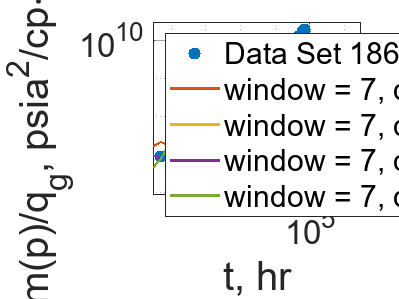

% Plot
loglog(noisy_RNP_186.t, noisy_RNP_186.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 186");
% title("Noisy RNP Data Set 186", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_186_71 = smooth(logRNP_186, 7, "sgolay", 1);
smoothedRNP_186_71 = exp(smoothedLogRNP_186_71);
residual_186_71 = (true_RNP.RNP - smoothedRNP_186_71) ./ (0.3413 .* true_RNP.RNP);
sse_186_71 = sum(residual_186_71 .^ 2);
loglog(noisy_RNP_186.t, smoothedRNP_186_71, "-", "LineWidth", 1.3, "DisplayName", "window = 7, degree = 1");
hold on;

% Degree = 2
smoothedLogRNP_186_72 = smooth(logRNP_186, 7, "sgolay", 2);
smoothedRNP_186_72 = exp(smoothedLogRNP_186_72);
residual_186_72 = (true_RNP.RNP - smoothedRNP_186_72) ./ (0.3413 .* true_RNP.RNP);
sse_186_72 = sum(residual_186_72 .^ 2);
loglog(noisy_RNP_186.t, smoothedRNP_186_72, "-", "LineWidth", 1.3, "DisplayName", "window = 7, degree = 2");
hold on;

% Degree = 3
smoothedLogRNP_186_73 = smooth(logRNP_186, 7, "sgolay", 3);
smoothedRNP_186_73 = exp(smoothedLogRNP_186_73);
residual_186_73 = (true_RNP.RNP - smoothedRNP_186_73) ./ (0.3413 .* true_RNP.RNP);
sse_186_73 = sum(residual_186_73 .^ 2);
loglog(noisy_RNP_186.t, smoothedRNP_186_73, "-", "LineWidth", 1.3, "DisplayName", "window = 7, degree = 3");
hold on;

% Degree = 4
smoothedLogRNP_186_74 = smooth(logRNP_186, 7, "sgolay", 4);
smoothedRNP_186_74 = exp(smoothedLogRNP_186_74);
residual_186_74 = (true_RNP.RNP - smoothedRNP_186_74) ./ (0.3413 .* true_RNP.RNP);
sse_186_74 = sum(residual_186_74 .^ 2);
loglog(noisy_RNP_186.t, smoothedRNP_186_74, "-", "LineWidth", 1.3, "DisplayName", "window = 7, degree = 4");
legend("Location", "northwest");
hold off;

#### Window: 9

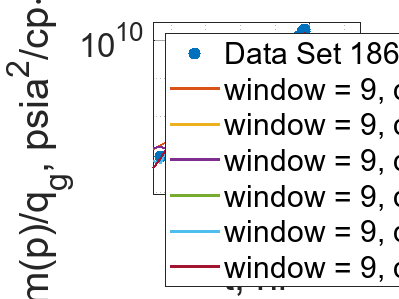

% Plot
loglog(noisy_RNP_186.t, noisy_RNP_186.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 186");
% title("Noisy RNP Data Set 186", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_186_91 = smooth(logRNP_186, 9, "sgolay", 1);
smoothedRNP_186_91 = exp(smoothedLogRNP_186_91);
residual_186_91 = (true_RNP.RNP - smoothedRNP_186_91) ./ (0.3413 .* true_RNP.RNP);
sse_186_91 = sum(residual_186_91 .^ 2);
loglog(noisy_RNP_186.t, smoothedRNP_186_91, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 1");
hold on;

% Degree = 2
smoothedLogRNP_186_92 = smooth(logRNP_186, 9, "sgolay", 2);
smoothedRNP_186_92 = exp(smoothedLogRNP_186_92);
residual_186_92 = (true_RNP.RNP - smoothedRNP_186_92) ./ (0.3413 .* true_RNP.RNP);
sse_186_92 = sum(residual_186_92 .^ 2);
loglog(noisy_RNP_186.t, smoothedRNP_186_92, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 2");
hold on;

% Degree = 3
smoothedLogRNP_186_93 = smooth(logRNP_186, 9, "sgolay", 3);
smoothedRNP_186_93 = exp(smoothedLogRNP_186_93);
residual_186_93 = (true_RNP.RNP - smoothedRNP_186_93) ./ (0.3413 .* true_RNP.RNP);
sse_186_93 = sum(residual_186_93 .^ 2);
loglog(noisy_RNP_186.t, smoothedRNP_186_93, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 3");
hold on;

% Degree = 4
smoothedLogRNP_186_94 = smooth(logRNP_186, 9, "sgolay", 4);
smoothedRNP_186_94 = exp(smoothedLogRNP_186_94);
residual_186_94 = (true_RNP.RNP - smoothedRNP_186_94) ./ (0.3413 .* true_RNP.RNP);
sse_186_94 = sum(residual_186_94 .^ 2);
loglog(noisy_RNP_186.t, smoothedRNP_186_94, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 4");
hold on;

% Degree = 5
smoothedLogRNP_186_95 = smooth(logRNP_186, 9, "sgolay", 5);
smoothedRNP_186_95 = exp(smoothedLogRNP_186_95);
residual_186_95 = (true_RNP.RNP - smoothedRNP_186_95) ./ (0.3413 .* true_RNP.RNP);
sse_186_95 = sum(residual_186_95 .^ 2);
loglog(noisy_RNP_186.t, smoothedRNP_186_95, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 5");
hold on;

% Degree = 6
smoothedLogRNP_186_96 = smooth(logRNP_186, 9, "sgolay", 6);
smoothedRNP_186_96 = exp(smoothedLogRNP_186_96);
residual_186_96 = (true_RNP.RNP - smoothedRNP_186_96) ./ (0.3413 .* true_RNP.RNP);
sse_186_96 = sum(residual_186_96 .^ 2);
loglog(noisy_RNP_186.t, smoothedRNP_186_96, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 6");
legend("Location", "northwest");
hold off;

#### Window: 11

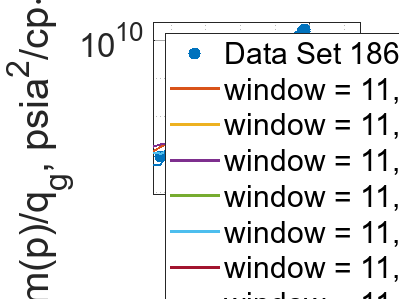

% Plot
loglog(noisy_RNP_186.t, noisy_RNP_186.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 186");
% title("Noisy RNP Data Set 186", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_186_111 = smooth(logRNP_186, 11, "sgolay", 1);
smoothedRNP_186_111 = exp(smoothedLogRNP_186_111);
residual_186_111 = (true_RNP.RNP - smoothedRNP_186_111) ./ (0.3413 .* true_RNP.RNP);
sse_186_111 = sum(residual_186_111 .^ 2);
loglog(noisy_RNP_186.t, smoothedRNP_186_111, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 1");
hold on;

% Degree = 2
smoothedLogRNP_186_112 = smooth(logRNP_186, 11, "sgolay", 2);
smoothedRNP_186_112 = exp(smoothedLogRNP_186_112);
residual_186_112 = (true_RNP.RNP - smoothedRNP_186_112) ./ (0.3413 .* true_RNP.RNP);
sse_186_112 = sum(residual_186_112 .^ 2);
loglog(noisy_RNP_186.t, smoothedRNP_186_112, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 2");
hold on;

% Degree = 3
smoothedLogRNP_186_113 = smooth(logRNP_186, 11, "sgolay", 3);
smoothedRNP_186_113 = exp(smoothedLogRNP_186_113);
residual_186_113 = (true_RNP.RNP - smoothedRNP_186_113) ./ (0.3413 .* true_RNP.RNP);
sse_186_113 = sum(residual_186_113 .^ 2);
loglog(noisy_RNP_186.t, smoothedRNP_186_113, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 3");
hold on;

% Degree = 4
smoothedLogRNP_186_114 = smooth(logRNP_186, 11, "sgolay", 4);
smoothedRNP_186_114 = exp(smoothedLogRNP_186_114);
residual_186_114 = (true_RNP.RNP - smoothedRNP_186_114) ./ (0.3413 .* true_RNP.RNP);
sse_186_114 = sum(residual_186_114 .^ 2);
loglog(noisy_RNP_186.t, smoothedRNP_186_114, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 4");
hold on;

% Degree = 5
smoothedLogRNP_186_115 = smooth(logRNP_186, 11, "sgolay", 5);
smoothedRNP_186_115 = exp(smoothedLogRNP_186_115);
residual_186_115 = (true_RNP.RNP - smoothedRNP_186_115) ./ (0.3413 .* true_RNP.RNP);
sse_186_115 = sum(residual_186_115 .^ 2);
loglog(noisy_RNP_186.t, smoothedRNP_186_115, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 5");
hold on;

% Degree = 6
smoothedLogRNP_186_116 = smooth(logRNP_186, 11, "sgolay", 6);
smoothedRNP_186_116 = exp(smoothedLogRNP_186_116);
residual_186_116 = (true_RNP.RNP - smoothedRNP_186_116) ./ (0.3413 .* true_RNP.RNP);
sse_186_116 = sum(residual_186_116 .^ 2);
loglog(noisy_RNP_186.t, smoothedRNP_186_116, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 6");
hold on;

% Degree = 7
smoothedLogRNP_186_117 = smooth(logRNP_186, 11, "sgolay", 7);
smoothedRNP_186_117 = exp(smoothedLogRNP_186_117);
residual_186_117 = (true_RNP.RNP - smoothedRNP_186_117) ./ (0.3413 .* true_RNP.RNP);
sse_186_117 = sum(residual_186_117 .^ 2);
loglog(noisy_RNP_186.t, smoothedRNP_186_117, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 7");
legend("Location", "northwest");
hold off;